## NLM Denoising

clear variables;

% inital conditions
[image,file_extension] = deal("images/lenna","jpg");
[method,method_name] = deal(@BlockNLM,"BlockNLM");

% file names
noisy = strcat(image,"_MZ20.", file_extension);
clean = strcat(image,"_orig.", file_extension);
denoised = strcat(image,"_",method_name,".",file_extension);

uClean = imread(clean);
uClean = double(uClean);

u0 = imread(noisy);
u0 = double(u0);

h = 22; % subject to adjustment

tic
u = method(u0,h);
toc

Elapsed time is 4.649617 seconds.


ssim_noisy = SSIM(u0,uClean);
psnr_noisy = PSNR(u0, uClean);

ssim_denoised = SSIM(u,uClean);
psnr_denoised = PSNR(u, uClean);

u = uint8(u);

imwrite(u,denoised);

disp(method_name + " Denoising Results:");

BlockNLM Denoising Results:


disp("Noisy");

Noisy


disp("ssim = " + ssim_noisy + ", psnr = " + psnr_noisy);

ssim = 0.95028, psnr = 24.3045


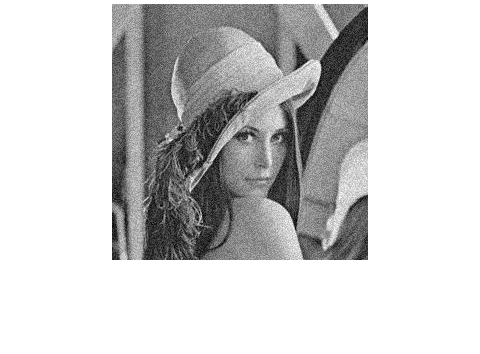

imshow(noisy);

disp("Denoised (h = " + h + ")");

Denoised (h = 22)


disp("ssim = " + ssim_denoised + ", psnr = " + psnr_denoised);

ssim = 0.98963, psnr = 31.4313


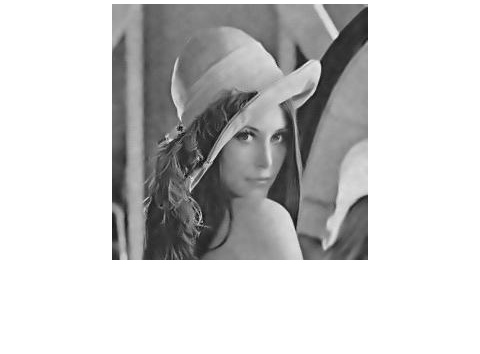

imshow(denoised);

disp("original");

original


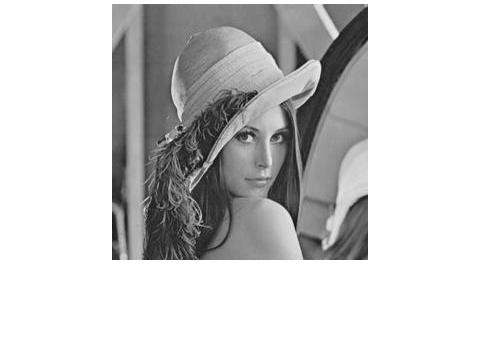

imshow(clean);